## Hessian Update: ‘bfgs’

## 1

clc
clear all
options = optimoptions('fminunc','Display','iter',...
    'Algorithm','quasi-newton','HessUpdate','bfgs','PlotFcn','optimplotfval');
fun = @fminfunc3;
x0 =[0 0 0 0 0 0 0 0];
[x,fval,exitflag,output] = fminunc(fun,x0,options)

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           9          16.1423                           4.4
     1          18          4.71746       0.227421           1.66  
     2          36           4.0521        0.44942        0.00414  
     3          45          4.05209              1       0.000845  
     4          54          4.05209              1       7.75e-07  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping crit

x =     0.8771    0.8771    0.8771    0.8771    0.8771    0.8771    0.8771         0


fval = 4.0521

exitflag = 1

output = struct with fields:
       iterations: 4
        funcCount: 54
         stepsize: 2.0777e-04
     lssteplength: 1
    firstorderopt: 7.7486e-07
        algorithm: 'quasi-newton'
          message: 'Local minimum found.↵↵Optimization completed because the size of the gradient is less than↵the value of the optimality tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The first-order optimality measure, 1.435690e-07, is less ↵than options.OptimalityTolerance = 1.000000e-06.'


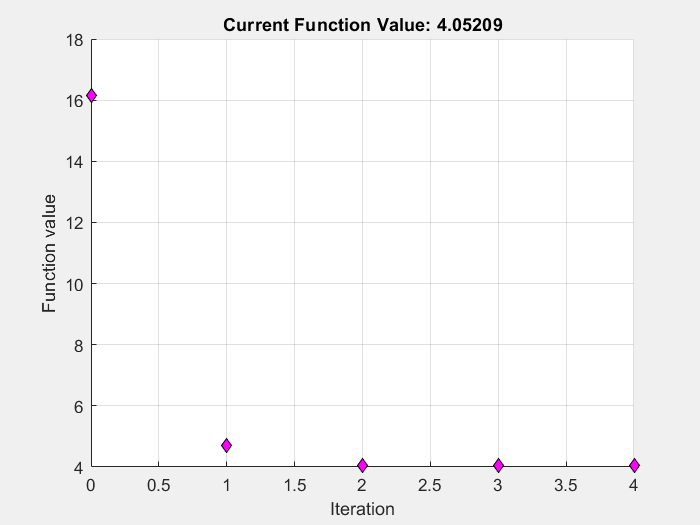

grid on;

## 2 - a

clc
clear all
options = optimoptions('fminunc','Display','iter',...
    'Algorithm','quasi-newton','HessUpdate','bfgs','PlotFcn','optimplotfval');
fun = @fminfunc3;
x0 =[-5 -1 0.3 4 2 0.8 1.5 7];
[x,fval,exitflag,output] = fminunc(fun,x0,options)

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           9          67.0637                          27.8
     1          45          62.4896     0.00389727           16.6  
     2          54          61.1071              1           12.9  
     3          72          58.1559       0.175956           8.69  
     4          90           57.231       0.540649           7.25  
     5          99          57.0306              1           6.75  
     6         108          56.0937              1           10.7  
     7         117          55.8117              1           10.5  
     8         126          55.6019              1           1.81  
     9         135          55.5742              1            1.8  
    10         144            55.55              1           1.77  
    11         153          55.5205              1           1.73  
    12         162          55.4819              

x =    -5.0952   -1.2399    0.8771    4.0327    2.2523    0.8771    0.8771    7.0000


fval = 55.0794

exitflag = 1

output = struct with fields:
       iterations: 28
        funcCount: 306
         stepsize: 1.1353e-06
     lssteplength: 1
    firstorderopt: 2.0589e-06
        algorithm: 'quasi-newton'
          message: 'Local minimum found.↵↵Optimization completed because the size of the gradient is less than↵the value of the optimality tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The first-order optimality measure, 7.142481e-08, is less ↵than options.OptimalityTolerance = 1.000000e-06.'


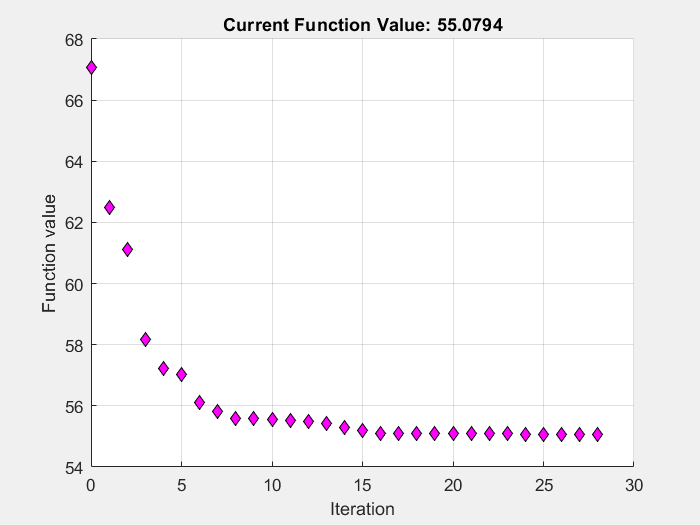

grid on;

## 2 - b

clc
clear all
options = optimoptions('fminunc','Display','iter','OptimalityTolerance',1e-10,...
    'Algorithm','quasi-newton','HessUpdate','bfgs','PlotFcn','optimplotfval');
fun = @fminfunc3;
x0 =[-5 -1 0.3 4 2 0.8 1.5 7];
[x,fval,exitflag,output] = fminunc(fun,x0,options)

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           9          67.0637                          27.8
     1          45          62.4896     0.00389727           16.6  
     2          54          61.1071              1           12.9  
     3          72          58.1559       0.175956           8.69  
     4          90           57.231       0.540649           7.25  
     5          99          57.0306              1           6.75  
     6         108          56.0937              1           10.7  
     7         117          55.8117              1           10.5  
     8         126          55.6019              1           1.81  
     9         135          55.5742              1            1.8  
    10         144            55.55              1           1.77  
    11         153          55.5205              1           1.73  
    12         162          55.4819              

x =    -5.0952   -1.2399    0.8771    4.0327    2.2523    0.8771    0.8771    7.0000


fval = 55.0794

exitflag = 2

output = struct with fields:
       iterations: 28
        funcCount: 306
         stepsize: 1.1353e-06
     lssteplength: 1
    firstorderopt: 2.0589e-06
        algorithm: 'quasi-newton'
          message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.310155e-07, is↵less than options.StepTolerance = 1.000000e-06.'


grid on;

## 3 - a

clc
clear all
options = optimoptions('fminunc','Display','iter',...
    'Algorithm','quasi-newton','HessUpdate','bfgs','PlotFcn','optimplotfval');
fun = @fminfunc3;
x0 =[-10 -5 4 -3 2 -1 0 10];
[x,fval,exitflag,output] = fminunc(fun,x0,options)

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           9          201.359                          80.3
     1          18          187.359      0.0124551             74  
     2          27          184.272              1           48.9  
     3          36          180.399              1             43  
     4          72          159.454       0.992243           42.5  
     5          99           159.06      0.0279975           43.4  
     6         108          153.554              1           65.9  
     7         117          145.904              1           22.4  
     8         135          144.791       0.323895           18.4  
     9         153          144.486       0.366496           12.6  
    10         171          144.369       0.478936           2.91  
    11         180          144.342              1           2.32  
    12         189          144.306              

x =    -7.0127   -5.6311    4.0327   -2.5508    2.9906   -1.9826    0.8771   10.0000


fval = 143.7651

exitflag = 1

output = struct with fields:
       iterations: 21
        funcCount: 279
         stepsize: 1.2886e-06
     lssteplength: 1
    firstorderopt: 3.8078e-06
        algorithm: 'quasi-newton'
          message: 'Local minimum found.↵↵Optimization completed because the size of the gradient is less than↵the value of the optimality tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The first-order optimality measure, 4.684267e-08, is less ↵than options.OptimalityTolerance = 1.000000e-06.'


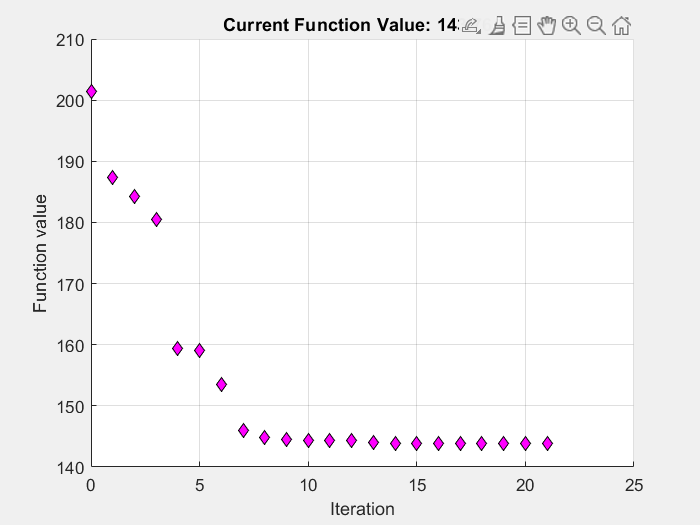

grid on;

## 3 - b

clc
clear all
options = optimoptions('fminunc','Display','iter','MaxFunctionEvaluations',1e500,...
    'Algorithm','quasi-newton','HessUpdate','bfgs','PlotFcn','optimplotfval');
fun = @fminfunc3;
x0 =[-10 -5 4 -3 2 -1 0 10];
[x,fval,exitflag,output] = fminunc(fun,x0,options)

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           9          201.359                          80.3
     1          18          187.359      0.0124551             74  
     2          27          184.272              1           48.9  
     3          36          180.399              1             43  
     4          72          159.454       0.992243           42.5  
     5          99           159.06      0.0279975           43.4  
     6         108          153.554              1           65.9  
     7         117          145.904              1           22.4  
     8         135          144.791       0.323895           18.4  
     9         153          144.486       0.366496           12.6  
    10         171          144.369       0.478936           2.91  
    11         180          144.342              1           2.32  
    12         189          144.306              

x =    -7.0127   -5.6311    4.0327   -2.5508    2.9906   -1.9826    0.8771   10.0000


fval = 143.7651

exitflag = 1

output = struct with fields:
       iterations: 21
        funcCount: 279
         stepsize: 1.2886e-06
     lssteplength: 1
    firstorderopt: 3.8078e-06
        algorithm: 'quasi-newton'
          message: 'Local minimum found.↵↵Optimization completed because the size of the gradient is less than↵the value of the optimality tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The first-order optimality measure, 4.684267e-08, is less ↵than options.OptimalityTolerance = 1.000000e-06.'


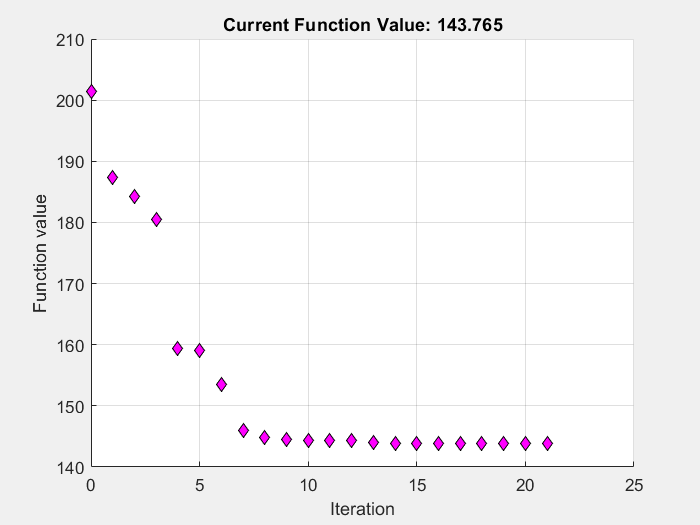

grid on;

## Hessian Update: ‘dfp’

## 1 - a

clc
clear all
options = optimoptions('fminunc','Display','iter',...
    'Algorithm','quasi-newton','HessUpdate','dfp','PlotFcn','optimplotfval');
fun = @fminfunc3;
x0 =[0 0 0 0 0 0 0 0];
[x,fval,exitflag,output] = fminunc(fun,x0,options)

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           9          16.1423                           4.4
     1          18          4.71746       0.227421           1.66  
     2          36           4.0521        0.44942        0.00414  
     3          45          4.05209              1       0.000845  
     4          54          4.05209              1       7.75e-07  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping crit

x =     0.8771    0.8771    0.8771    0.8771    0.8771    0.8771    0.8771         0


fval = 4.0521

exitflag = 1

output = struct with fields:
       iterations: 4
        funcCount: 54
         stepsize: 2.0777e-04
     lssteplength: 1
    firstorderopt: 7.7486e-07
        algorithm: 'quasi-newton'
          message: 'Local minimum found.↵↵Optimization completed because the size of the gradient is less than↵the value of the optimality tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The first-order optimality measure, 1.435690e-07, is less ↵than options.OptimalityTolerance = 1.000000e-06.'


grid on;

## 1 - b

clc
clear all
options = optimoptions('fminunc','Display','iter','MaxFunctionEvaluations',1e5,...
    'Algorithm','quasi-newton','HessUpdate','dfp','PlotFcn','optimplotfval');
fun = @fminfunc3;
x0 =[0 0 0 0 0 0 0 0];
[x,fval,exitflag,output] = fminunc(fun,x0,options)

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           9          16.1423                           4.4
     1          18          4.71746       0.227421           1.66  
     2          36           4.0521        0.44942        0.00414  
     3          45          4.05209              1       0.000845  
     4          54          4.05209              1       7.75e-07  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping crit

x =     0.8771    0.8771    0.8771    0.8771    0.8771    0.8771    0.8771         0


fval = 4.0521

exitflag = 1

output = struct with fields:
       iterations: 4
        funcCount: 54
         stepsize: 2.0777e-04
     lssteplength: 1
    firstorderopt: 7.7486e-07
        algorithm: 'quasi-newton'
          message: 'Local minimum found.↵↵Optimization completed because the size of the gradient is less than↵the value of the optimality tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The first-order optimality measure, 1.435690e-07, is less ↵than options.OptimalityTolerance = 1.000000e-06.'


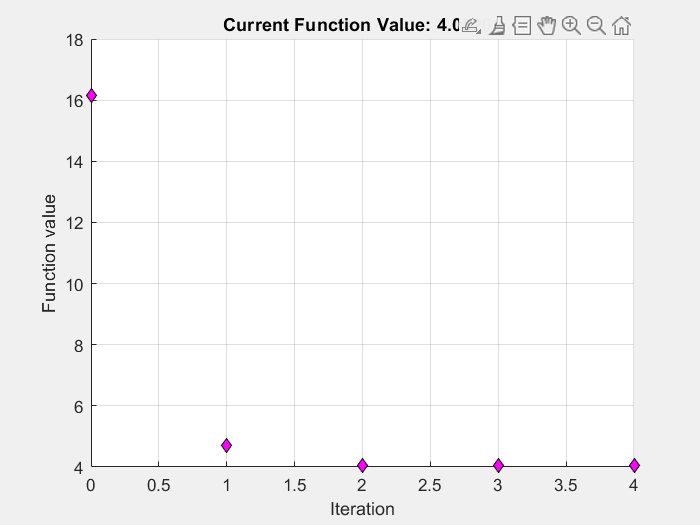

grid on;

## 1 - c

clc
clear all
options = optimoptions('fminunc','Display','iter','MaxFunctionEvaluations',1e5,...
    'MaxIterations',3e3,'Algorithm','quasi-newton','HessUpdate','dfp','PlotFcn','optimplotfval');
fun = @fminfunc3;
x0 =[0 0 0 0 0 0 0 0];
[x,fval,exitflag,output] = fminunc(fun,x0,options)

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           9          16.1423                           4.4
     1          18          4.71746       0.227421           1.66  
     2          36           4.0521        0.44942        0.00414  
     3          45          4.05209              1       0.000845  
     4          54          4.05209              1       7.75e-07  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping crit

x =     0.8771    0.8771    0.8771    0.8771    0.8771    0.8771    0.8771         0


fval = 4.0521

exitflag = 1

output = struct with fields:
       iterations: 4
        funcCount: 54
         stepsize: 2.0777e-04
     lssteplength: 1
    firstorderopt: 7.7486e-07
        algorithm: 'quasi-newton'
          message: 'Local minimum found.↵↵Optimization completed because the size of the gradient is less than↵the value of the optimality tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The first-order optimality measure, 1.435690e-07, is less ↵than options.OptimalityTolerance = 1.000000e-06.'


grid on;

## 2

clc
clear all
options = optimoptions('fminunc','Display','iter','MaxFunctionEvaluations',1e5,...
    'MaxIterations',3e3,'Algorithm','quasi-newton','HessUpdate','dfp','PlotFcn','optimplotfval');
fun = @fminfunc3;
x0 =[-5 0.5 0.3 0.4 0.2 0.8 1.5 7];
[x,fval,exitflag,output] = fminunc(fun,x0,options)

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           9          50.0222                          27.8
     1          45          46.7379     0.00302265             13  
     2          63          46.5042       0.172331            9.8  
     3          81          43.7379        5.98353           29.5  
     4          90          43.0323              1           29.9  
     5          99          42.6691              1           21.8  
     6         108          42.3254              1           6.23  
     7         117          42.1968              1           2.12  
     8         126          42.0916              1           8.98  
     9         135          42.0129              1           13.3  
    10         144          41.9505              1           15.3  
    11         153          41.8887              1           16.4  
    12         162           41.832              

x =    -5.0952    0.8771    0.8771    0.8771    0.8771    0.8771    0.8771    7.0000


fval = 40.6846

exitflag = 2

output = struct with fields:
       iterations: 76
        funcCount: 756
         stepsize: 1.6360e-06
     lssteplength: 1
    firstorderopt: 3.4332e-05
        algorithm: 'quasi-newton'
          message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 7.624643e-07, is↵less than options.StepTolerance = 1.000000e-06.'


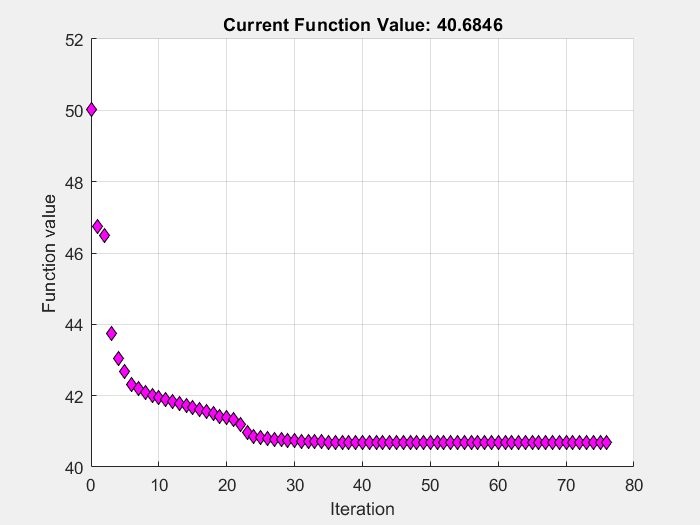

grid on;

## 3

clc
clear all
options = optimoptions('fminunc','Display','iter','MaxFunctionEvaluations',1e7,...
    'MaxIterations',10e3,'Algorithm','quasi-newton','HessUpdate','dfp','PlotFcn','optimplotfval');
fun = @fminfunc3;
x0 =[-10 0.5 0.4 -3 0.2 -1 0 10];
[x,fval,exitflag,output] = fminunc(fun,x0,options)

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           9          151.488                          80.3
     1          45          132.204      0.0120042           44.8  
     2          54          131.062              1             54  
     3          63          127.944              1           7.87  
     4          81          127.875       0.438974           13.4  
     5         108          119.977             19           13.5  
     6         126           119.59       0.304499           12.1  
     7         135          119.129              1           12.5  
     8         144          118.915              1           8.79  
     9         153          118.697              1           7.84  
    10         171          118.238        9.43471           7.26  
    11         180          118.165              1           6.41  
    12         189          117.919              

x =    -8.8733    0.8771    0.8771   -2.5508    0.8771   -1.2399    0.8771   10.0000


fval = 117.8288

exitflag = 1

output = struct with fields:
       iterations: 44
        funcCount: 477
         stepsize: 3.1233e-06
     lssteplength: 1
    firstorderopt: 1.3845e-05
        algorithm: 'quasi-newton'
          message: 'Local minimum found.↵↵Optimization completed because the size of the gradient is less than↵the value of the optimality tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The first-order optimality measure, 1.703195e-07, is less ↵than options.OptimalityTolerance = 1.000000e-06.'


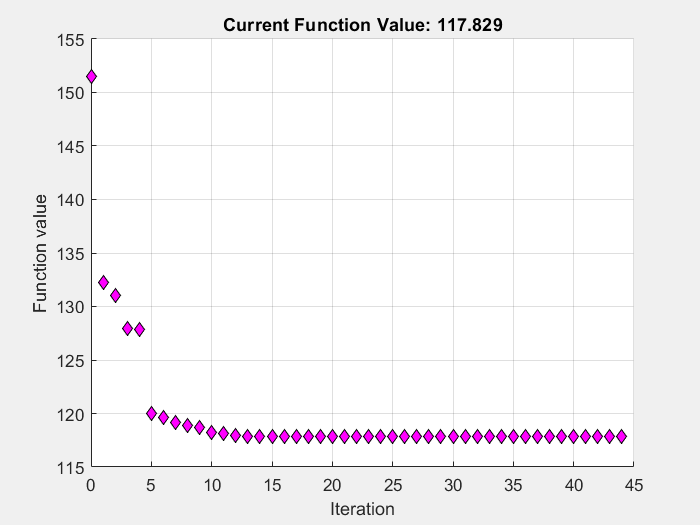

grid on;

## Hessian Update: ‘steepdesc’

## 1

clc
clear all
options = optimoptions('fminunc','Display','iter',...
    'Algorithm','quasi-newton','HessUpdate','steepdesc','PlotFcn','optimplotfval');
fun = @fminfunc3;
x0 =[0 0 0 0 0 0 0 0];
[x,fval,exitflag,output] = fminunc(fun,x0,options)

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           9          16.1423                           4.4
     1          18          4.71746       0.227421           1.66  
     2          36          4.11864            0.1          0.426  
     3          54          4.05211            0.1        0.00712  
     4          72          4.05209            0.1       0.000536  
     5          90          4.05209            0.1       4.12e-05  
     6         108          4.05209            0.1       3.16e-06  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<<a href = "matlab

x =     0.8771    0.8771    0.8771    0.8771    0.8771    0.8771    0.8771         0


fval = 4.0521

exitflag = 1

output = struct with fields:
       iterations: 6
        funcCount: 108
         stepsize: 1.0890e-05
     lssteplength: 0.1000
    firstorderopt: 3.1590e-06
        algorithm: 'quasi-newton'
          message: 'Local minimum found.↵↵Optimization completed because the size of the gradient is less than↵the value of the optimality tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The first-order optimality measure, 5.853199e-07, is less ↵than options.OptimalityTolerance = 1.000000e-06.'


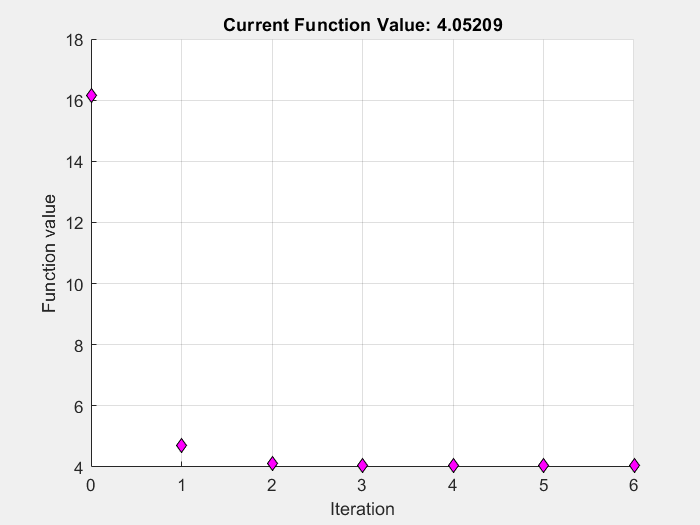

grid on;

## 2 - a

clc
clear all
options = optimoptions('fminunc','Display','iter','MaxFunctionEvaluations',1e7,...
    'MaxIterations',1e4,'Algorithm','quasi-newton','HessUpdate','steepdesc','PlotFcn','optimplotfval');
fun = @fminfunc3;
x0 =[-0.5 0.5 0.5 0.4 0.2 0.8 5.5 4];
[x,fval,exitflag,output] = fminunc(fun,x0,options)

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           9          32.4259                          11.3
     1          36          28.8443      0.0782282           15.1  
     2          54          6.68456       0.247203           12.9  
     3          90          5.63927     0.00698173           7.99  
     4         126          5.25468      0.0102619            1.4  
     5         153          5.14686      0.0399865           2.84  
     6         180           5.1043           0.01          0.529  
     7         207          5.09264      0.0232972           0.97  
     8         243          5.08539       0.011033          0.329  
     9         270          5.08089       0.023393          0.609  
    10         297          5.07804      0.0109137          0.203  
    11         324          5.07618      0.0245826            0.4  
    12         351            5.075      0.010751

x =     0.8771    0.8772    0.8772    0.8771    0.8771    0.8771    2.2523    4.0000


fval = 5.0729

exitflag = 2

output = struct with fields:
       iterations: 46
        funcCount: 1269
         stepsize: 2.6365e-06
     lssteplength: 0.0110
    firstorderopt: 7.0287e-05
        algorithm: 'quasi-newton'
          message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 6.888432e-07, is↵less than options.StepTolerance = 1.000000e-06.'


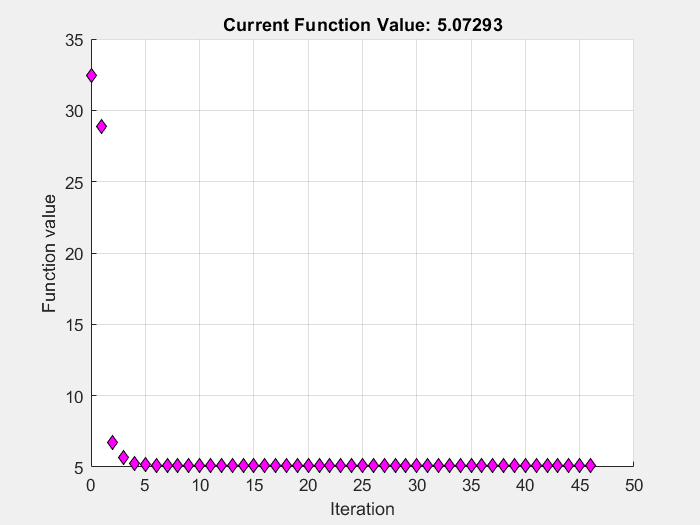

grid on;

## 2 - b

clc
clear all
options = optimoptions('fminunc','Display','iter','MaxFunctionEvaluations',1e7,...
    'MaxIterations',1e4,'OptimalityTolerance',1e-10,'Algorithm','quasi-newton','HessUpdate','steepdesc','PlotFcn','optimplotfval');
fun = @fminfunc3;
x0 =[-0.5 0.5 0.5 0.4 0.2 0.8 5.5 4];
[x,fval,exitflag,output] = fminunc(fun,x0,options)

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           9          32.4259                          11.3
     1          36          28.8443      0.0782282           15.1  
     2          54          6.68456       0.247203           12.9  
     3          90          5.63927     0.00698173           7.99  
     4         126          5.25468      0.0102619            1.4  
     5         153          5.14686      0.0399865           2.84  
     6         180           5.1043           0.01          0.529  
     7         207          5.09264      0.0232972           0.97  
     8         243          5.08539       0.011033          0.329  
     9         270          5.08089       0.023393          0.609  
    10         297          5.07804      0.0109137          0.203  
    11         324          5.07618      0.0245826            0.4  
    12         351            5.075      0.010751

x =     0.8771    0.8772    0.8772    0.8771    0.8771    0.8771    2.2523    4.0000


fval = 5.0729

exitflag = 2

output = struct with fields:
       iterations: 46
        funcCount: 1269
         stepsize: 2.6365e-06
     lssteplength: 0.0110
    firstorderopt: 7.0287e-05
        algorithm: 'quasi-newton'
          message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 6.888432e-07, is↵less than options.StepTolerance = 1.000000e-06.'


grid on;

## 3

clc
clear all
options = optimoptions('fminunc','Display','iter','MaxFunctionEvaluations',1e7,...
    'MaxIterations',1e4,'OptimalityTolerance',1e-10,'Algorithm','quasi-newton','HessUpdate','steepdesc','PlotFcn','optimplotfval');
fun = @fminfunc3;
x0 =[-10 0.5 0.4 -3 2 -1 0 10];
[x,fval,exitflag,output] = fminunc(fun,x0,options)

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           9          153.892                          80.3
     1          45          132.738      0.0119363           44.8  
     2          63          110.066            0.1            104  
     3          90          6.78511      0.0885613           3.69  
     4         117          4.53064       0.141205           1.66  
     5         135          4.13652            0.1           1.07  
     6         153          4.05537            0.1          0.257  
     7         171          4.05209            0.1        0.00617  
     8         189          4.05209            0.1        0.00048  
     9         207          4.05209            0.1       3.68e-05  
    10         225          4.05209            0.1       2.86e-06  
    11         243          4.05209            0.1       2.38e-07  



x =     0.8771    0.8771    0.8771    0.8771    0.8771    0.8771    0.8771   10.0000


fval = 4.0521

exitflag = 2

output = struct with fields:
       iterations: 11
        funcCount: 243
         stepsize: 2.8697e-07
     lssteplength: 0.1000
    firstorderopt: 2.3842e-07
        algorithm: 'quasi-newton'
          message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 1.524136e-07, is↵less than options.StepTolerance = 1.000000e-06.'


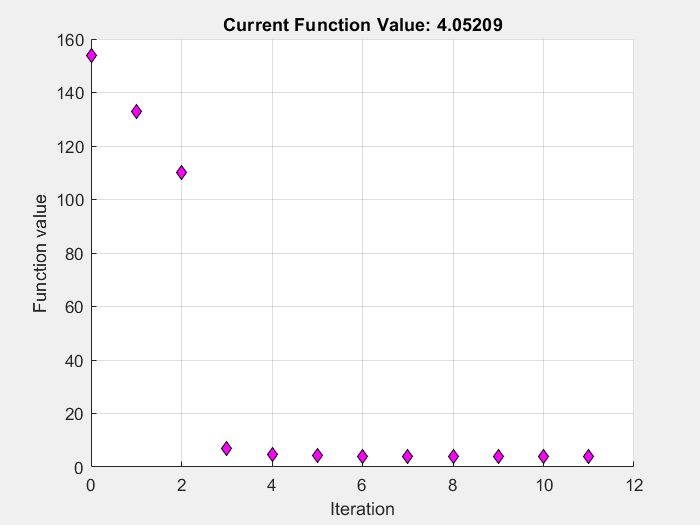

grid on;